# Examen Localización de un robot diferencial

Ana Itzel Hernández García 

Limpieza de pantalla

clear all
close all
clc

**Pregunta 1 **

Obtén la pose del robot en cada paso, integrando numéricamente siguiendo la suposición de Markov

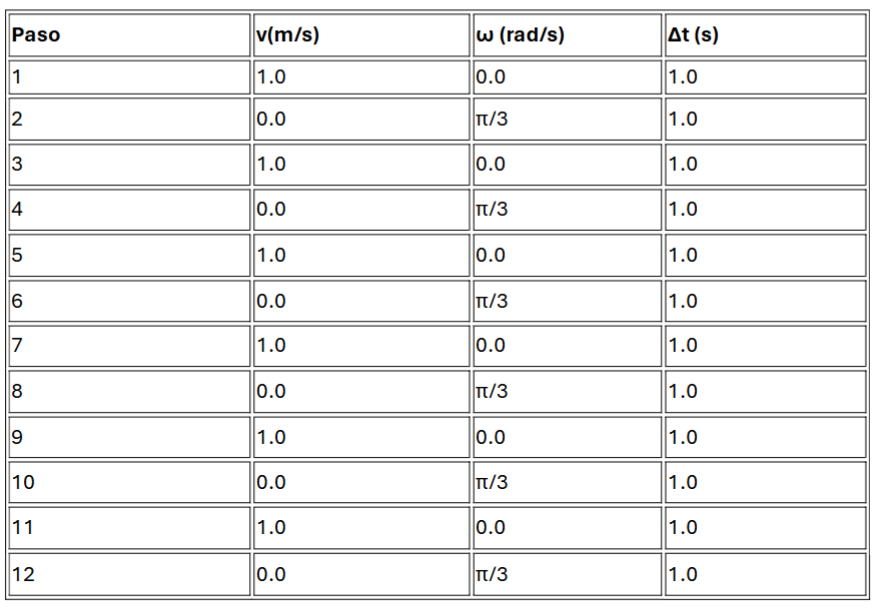

Posición inicial: (-1, -5, 0º)

x = -1;
y = -5; 
th = 0;
delta_t = 1;
N = 12; 

v = [1,0,1,0,1,0,1,0,1,0,1,0];
w = [0,pi/3,0,pi/3,0,pi/3,0,pi/3,0,pi/3,0,pi/3];

for i=1:N 
    if w(i) == 0
        x = x + v(i)* cos(th)* delta_t;
        y = y + v(i)* sin(th)* delta_t;
        th = th;
        sprintf("Paso: %d", i)
        sprintf("pose : x = %0.1f y = %0.1f θ = %0.1f", x, y,rad2deg(th))
    else 
        %Angular
        x = x - (v(i)/w(i) * sin(th)) + (v(i)/w(i) * sin(th + w(i)*delta_t));
        y = y + (v(i)/w(i) * cos(th)) - (v(i)/w(i) * cos(th + w(i)*delta_t));
        th = th + w(i)*delta_t;
        sprintf("Paso: %d", i)
        sprintf("pose : x = %0.1f y = %0.1f θ = %0.1f", x, y,rad2deg(th))
    end
end

ans = "Paso: 1"

ans = "pose : x = 0.0 y = -5.0 θ = 0.0"

ans = "Paso: 2"

ans = "pose : x = 0.0 y = -5.0 θ = 60.0"

ans = "Paso: 3"

ans = "pose : x = 0.5 y = -4.1 θ = 60.0"

ans = "Paso: 4"

ans = "pose : x = 0.5 y = -4.1 θ = 120.0"

ans = "Paso: 5"

ans = "pose : x = 0.0 y = -3.3 θ = 120.0"

ans = "Paso: 6"

ans = "pose : x = 0.0 y = -3.3 θ = 180.0"

ans = "Paso: 7"

ans = "pose : x = -1.0 y = -3.3 θ = 180.0"

ans = "Paso: 8"

ans = "pose : x = -1.0 y = -3.3 θ = 240.0"

ans = "Paso: 9"

ans = "pose : x = -1.5 y = -4.1 θ = 240.0"

ans = "Paso: 10"

ans = "pose : x = -1.5 y = -4.1 θ = 300.0"

ans = "Paso: 11"

ans = "pose : x = -1.0 y = -5.0 θ = 300.0"

ans = "Paso: 12"

ans = "pose : x = -1.0 y = -5.0 θ = 360.0"